# Actividad 5: Robot_Antropomorfico_3GDL

Daniel Castillo López

A01737357

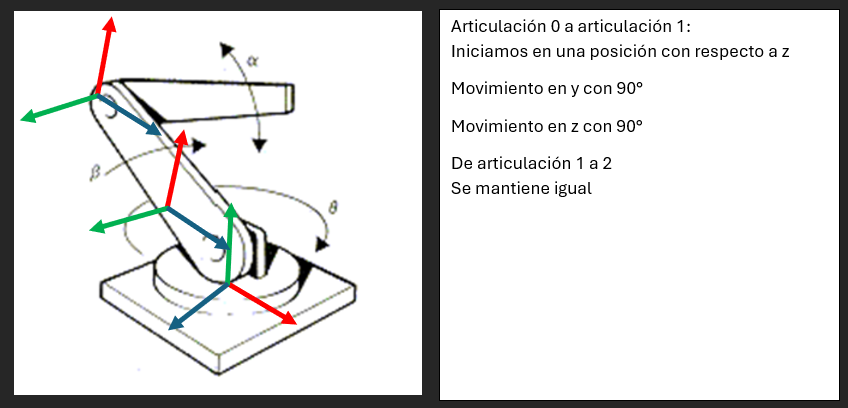

clear all
close all
clc

Posteriormente, se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

syms th1(t) th2(t) th3(t) t l1 l2 l3


Configuración del robot, 0 para junta rotacional

RP=[0 0 0];

Creamos el vector de coordenadas articulares

Q= [th1, th2, th3];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

(th1(t), th2(t), th3(t))




%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d          d          d        \
| -- th1(t), -- th2(t), -- th3(t) |
\ dt         dt         dt        /




%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);


## Cinemática Directa

### Articulación 1


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & -\mathrm{sen}\left(\theta \right) & 0\\
\mathrm{sen}\left(\theta \right) & \cos \left(\theta \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$$R_y \left(90\right)\left\lbrack \begin{array}{ccc}
\cos \left(90\right) & 0 & \mathrm{sen}\left(90\right)\\
0 & 1 & 0\\
-\mathrm{sen}\left(90\right) & 0 & \cos \left(90\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
-1 & 0 & 0
\end{array}\right\rbrack$$


$\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & -\mathrm{sen}\left(\theta \right) & 0\\
\mathrm{sen}\left(\theta \right) & \cos \left(\theta \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$x$\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
-1 & 0 & 0
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{ccc}
0 & -\mathrm{sen}\left(\theta \right) & \cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & \mathrm{sen}\left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack$


$$2\ldotp 1\left(\theta \right)$$

$$\left\lbrack \begin{array}{ccc}
0 & -\mathrm{sen}\left(\theta \right) & \cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & \mathrm{sen}\left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack$$



$$R_x \left(-90\right)\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(90\right) & -\sin \left(90\right)\\
0 & \sin \left(90\right) & \cos \left(90\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & -1\\
0 & 1 & 0
\end{array}\right\rbrack$$


$\left\lbrack \begin{array}{ccc}
0 & -\mathrm{sen}\left(\theta \right) & \cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & \mathrm{sen}\left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack$x$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & 1\\
0 & -1 & 0
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{ccc}
0 & \cos \left(\theta \right) & \mathrm{sen}\left(\theta \right)\\
0 & \mathrm{sen}\left(\theta \right) & -\cos \left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack$

%Articulación 1
%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 a 2
R(:,:,1)= [0  cos(th1)  sin(th1);
           0  sin(th1) -cos(th1);
          -1      0        0];

### Articulación 2

%Articulación 2
%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];

Se mantiene en la matriz de rotación z debido a que no presenta algun movimiento en su rotación 

%Matriz de rotación de la junta 2 a 3
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

### Articulación 3

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [l3*cos(th3); l3*sin(th3);0];
%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)=   [cos(th3) -sin(th3)  0;
             sin(th3)  cos(th3)  0;
              0         0        1];

Las matrices de transformación homogénea, combinan la rotación y traslación en un solo modelo matemático. Se construyen las matrices locales y globales de transformación para obtener la posición y orientación del extremo del robot en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


El bucle `for` recorre cada articulación del robot para calcular sus matrices de transformación homogénea locales y globales. Primero, genera la matriz de transformación local, que describe la posición y orientación de la articulación en relación con la anterior. Luego, obtiene la matriz de transformación global, que representa la posición y orientación en el sistema de referencia inercial, acumulando las transformaciones previas. Finalmente, extrae la matriz de rotación y el vector de posición, fundamentales para la cinemática directa y el cálculo del Jacobiano., desde este punto las explicaciones van sobre su posición con respecto a sus libertades que se encuentran en que ejes se mueven.

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str))
    T(:,:,i)= simplify(T(:,:,i))
    %pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/  0, cos(th1(t)),  sin(th1(t)),  0 \
|                                   |
|  0, sin(th1(t)), -cos(th1(t)),  0 |
|                                   |
| -1,      0,            0,      l1 |
|                                   |
\  0,      0,            0,       1 /



Matriz de Transformación global T1


$$\left(\begin{array}{cccc} 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{3}\left(t\right)\right) & \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2


$$\left(\begin{array}{cccc} 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ -\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{3}\left(t\right)\right) & \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A3


/ cos(th3(t)), -sin(th3(t)), 0, l3 cos(th3(t)) \
|                                              |
| sin(th3(t)),  cos(th3(t)), 0, l3 sin(th3(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T3


$$\left(\begin{array}{cccc} 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ -\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3} & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1} & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{2}\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3} & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1} & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{2}\\ -\sigma_{1} & \sigma_{3} & 0 & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)-l_{3}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{2}=l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)+l_{3}\,\sigma_{3}\\ \sigma_{3}=\sin\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}$$

## Cálculo del jacobiano lineal de forma diferencial

El Jacobiano es una matriz que relaciona las velocidades articulares con las velocidades lineales y angulares del extremo del robot. El Jacobiano lineal (Jv), relaciona velocidades articulares con velocidad lineal del extremo. Mientras que el Jacobiano angular (Jw), relaciona velocidades articulares con velocidad angular.

El Jacobiano diferencial es obtenido mediante derivadas parciales de la posición.

%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
pretty(jv_d);

## Cálculo del jacobiano lineal y angular de forma analítica

El jacobiano analítico es calculado mediante productos vectoriales, considerando el tipo de articulación

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Para articulaciones rotacionales, la velocidad lineal se obtiene mediante el producto cruzado entre el eje de rotación y la diferencia de posiciones, mientras que la velocidad angular se toma directamente del eje de rotación. Si no hay una matriz de rotación previa, se usa la identidad y la posición inicial. Para articulaciones prismáticas, la velocidad lineal es el eje de desplazamiento, y la angular es cero, ya que no hay rotación.

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/                     _________                                       \
|                      d                                              |
| #2 cos(th1(t)) #4 - -- th1(t) sin(th1(t)) #3 + l3 #1 cos(th1(t)) #6 |
|                     dt                                              |
|                                                                     |
|                     _________                                       |
|                      d                                              |
| #2 sin(th1(t)) #4 + -- th1(t) cos(th1(t)) #3 + l3 #1 sin(th1(t)) #6 |
|                     dt                                              |
|                                                                     |
\                           #2 #3 + l3 #1 #5                          /

where

         _________
          d
   #1 == -- th3(t)
         dt

         _________
          d
   #2 == -- th2(t)
         dt

   #3 == l2 sin(th2(t)) + l3 #5

   #4 == l2 cos(th2(t)) + l3 #6

   #5 ==

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W

/              / _________   _________ \ \
|              |  d           d        | |
|  sin(th1(t)) | -- th2(t) + -- th3(t) | |
|              \ dt          dt        / |
|                                        |
|              / _________   _________ \ |
|              |  d           d        | |
| -cos(th1(t)) | -- th2(t) + -- th3(t) | |
|              \ dt          dt        / |
|                                        |
|                _________               |
|                 d                      |
|                -- th1(t)               |
\                dt                      /



Está ligado a su espacio de tres dimensiones, siendo una combinación de términos en dependencia a las derivadas,como también esto lo podemos ver en su velocidad angular siendo como la segunda fila del robot sus tres dimensiones son afectadas en base al primer ángulo , el negativo representa la manera perpendicular entre si.